Irene Celestino - Daniele Poidomani 

16/11/2021

# Logbook 

## Es. 1

Abbiamo costruito il circuito, usando come resistenza del Gain Rg=1 kOhm e come resistenza del Source Rs=10 Ohm. Abbiamo preso per Rs la resistenza più bassa possibile, perché le correnti che scorrono nel circuito devono essere sotto 10 mA. 

## Es. 2 - Tensione di Soglia del MOSFET

Abbiamo collegato l'amperometro per misurare la corrente che scorre nel transistor (messo tra l'analog output CB21 e il drain). 

Abbiamo impostato con Vin_Vout_2C.vi per prima cosa Vdrain a 0.1 V. Misurando Vdrain con il multimetro si ottiene $0.999 \pm$ V.

Abbiamo poi cambiato Vgate (CB22) e misurato la corrente con l'amperometro e Vs (CB33):

- $V_g = 0.999 \pm 0.007$ V : $I = 0$ A  - $V_s = 0$ V

- $V_g=1.498 \pm 0.007$ V:  $I = 0.06 \pm 0.02 \mu$A - $V_s = 0$ V

- $V_g= 1.717 \pm 0.007$ V : $I=1.0 \pm 0.1 \mu$A - $V_s = 0$ V

- $V_g =1.800 \pm 0.007$ V : $I=2.9 \pm 0.1 \mu$A - $V_s = 0$ V

- $V_g =1.898 \pm 0.006$ V : $I = 9.8 \pm 0.1 \mu$A - $V_s= 0.22 \pm 0.08$ mV

- $V_g = 1.998 \pm 0.007$ V : $I = 32.97 \pm 0.04\mu$A - $V_s= 0.49 \pm 0.06$ mV

- $V_g=2.995 \pm 0.007$ V : $I= 4.05\pm 0.05$ mA - $V_s= 45.74 \pm 0.14$ mV 

- $V_g=3.994 \pm 0.007$ V :  $I= 4.880 \pm 0.004$ mA - $V_s= 52.04 \pm 0.09$ mV

Si può quindi stimare che $V_T$ è intorno ai 2 V, in accordo con il valore tipico riportato dal datasheet, 2.1 V

## Es. 3 - Corrente del Gain

Abbiamo collegato l'amperometro il serie alla resistenza del Gain (tra Rg e CB22) e misurato la corrente che scorre in Rg, variando Vg con Vin_Vout_2C.vi

Viene sempre una corrente di 0 A: il valore massimo misurato è $1.00 \pm 0.06 \mu$A per Vg = 4 V. 

Avevamo verificato che non scorresse corrente anche nell'esercizio precedente: abbiamo messo CB68 tra la resistenza e il Gain e la tensione che si misura lì è sempre compatibile con quella impostata nel vi, quindi non c'è caduta di tensione ai capi di Rg.

## Es. 4 e 5 - Aggiunta dell'OpAmp

La corrente $I_{DS}$ non entra nell'ingresso invertente dell'OpAmp, ma scorre nella resistenza di feeedback e poi entra nell'OpAmp dall'uscita. Ci serve quindi un OpAmp con una resistenza di ingresso molto alta, o almeno molto maggiore di Rtran. 

Abbiamo usato uA741C, in modo da lavorare in un range ampio di tensioni, tra -12 e 12 V, nonostante abbia una resistenza di ingresso più bassa di altri modelli a nostra disposizione. 

Abbiamo scelto Rtrans = 100 Ohm, di vari ordini di grandezza inferiore a quella dell'OpAmp, dell'ordine di 0.3-2 MOhm. 

## Es. 6 - Corrente di Drain VS Tensione di Drain

Abbiamo usato FET_vs_DRAIN.vi per misurare la curva $I_{DS}$ VS $V_{DS}$ al variare di $V_{GS}$.

Impostazioni sul vi (mantenute uguali per tutte le misure con FET_vs_DRAIN.vi e con FET_vs_GAIN.vi): 

- n misure = 100

- Fondoscala = 10 V per Vgs, 0.5 oppure 5 V per gli altri

Abbiamo preso la prima misura con $V_{GS}$= 2.5 V, poco sopra la soglia, con $V_{DS}$ che variava prima tra 0 e 0.5 V, per concentrarci sulla zona lineare, e poi tra 0 e 1 V, per studiare anche la zona di saturazione. 

$I_{DS}$ **per **$V_{DS}$ **tra 0 e 1 V**

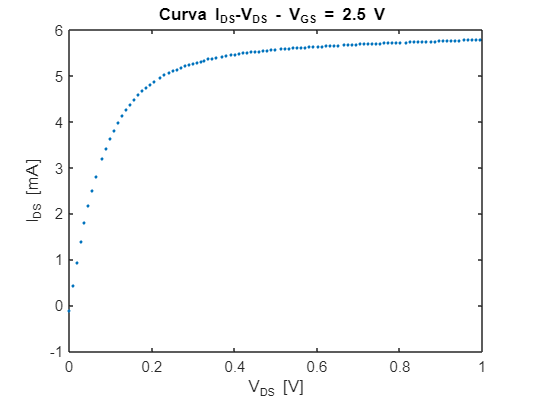

R=100;%ohm
dR=1;
datamat=readmatrix('Data LAB es 6 2');
Vd=datamat(:,1);
Id=datamat(:,2);
Vout=Id*R;
dig_V=2*2^(-12); %digitalizzazione
dVd=dig_V*ones(length(Id), 1);
dId=sqrt((dig_V/R)^2+(Vout/R^2*dR).^2); %digitalizzazione

plot(Vd, Id,'.')
title('Curva I_{DS}-V_{DS} - V_{GS} = 2.5 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{DS} [V]')

$I_{DS}$ **per **$V_{DS}$ **regime lineare**

datamat=readmatrix('Data LAB es 6');
Vd=datamat(:,1);
Id=datamat(:,2)*1e-3; %in A, misure in mA

Id_fit=Id(1:12);
Vd_fit=Vd(1:12);
Vout=Id_fit/R;

dig_Vout=20*2^(-12); %digitalizzazione
dig_V=1*2^(-12); %digitalizzazione
dVd=dig_V*ones(length(Id_fit), 1);
dId=sqrt((dig_Vout/R)^2+(Vout*dR/R^2).^2); %digitalizzazione

errorbar(Vd_fit, Id_fit*1e3, dId*1e3, dId*1e3, dVd, dVd, '.')
title('Curva I_{DS}-V_{DS} - V_{GS} = 2.5 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{DS} [V]')

%fit
[p, dp, chiqn, prod, corr]= fitpoli(1,Vd_fit, Id_fit, dId);
coefficiente=p(1)

coefficiente =    0.047350754441715


dcoefficiente=dp(1)

dcoefficiente =      8.714657711862921e-04


intercetta=p(2)

intercetta =     -1.786905603306556e-05


dintercetta=dp(2)

dintercetta =      2.670811537436160e-05


chiqn

chiqn =    1.430537295413253


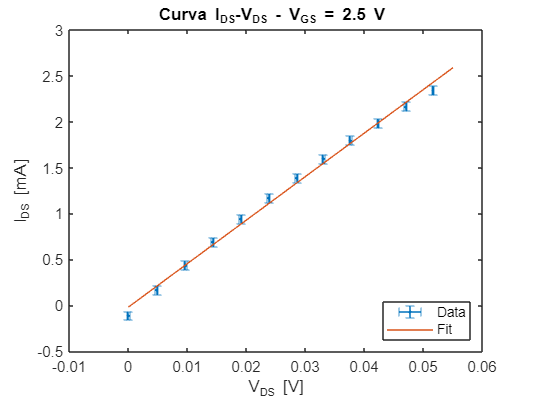

xx=linspace(0, 0.055, 100);
yy=p(1)*xx+p(2);

hold on 
plot(xx,yy*1e3)
hold off
legend('Data', 'Fit', 'Location','southeast')


i=1;
Vg(i)=2.5;
coeff(i)=p(1);
dcoeff(i)=dp(1);
fine_lin(i)=max(Vd_fit);

Risultati del fit lineare: 

- coefficiente = $47.4 \pm 0.08$ mA/V

- intercetta = $-17 \pm 26$ $\mu$A (compatibile con 0)

- 
$$\chi^2_{norm} = 1.43$$


## Es. 7 - Corrente di Drain VS Tensione di Drain per diversi Vgs

Abbiamo poi ripetuto la stessa misura variando $V_{GS}$. Abbiamo preso valori di $V_{GS}$ piccoli (fino a 4 V), perché volevamo mantenere la corrente sotto i 10 mA, o comunque sotto i 20 mA. Per correnti superiori a questa, infatti, l'OpAmp smette di funzionare perché la sua *Short-circuit output current* vale 25 mA.

Abbiamo quindi impostato il range di $V_{DS$ per rimanere a correnti basse, anche se per $V_{GS}$ = 3 e 4 V siamo arrivati a 20 mA. 

Valori scelti di $V_{GS}$: 2.2, 2.3, 2.4, 2.6, 3, 4 V

$I_{DS}$ **vs **$V_{DS}$ **per **$V_{GS}$ **= 2.3 V**

R=100;%ohm
dR=1;
datamat=readmatrix('Data LAB es 7 vg 2,3');
Vd=datamat(:,1);
Id=datamat(:,2)*1e-3; %in A, misure in mA

Id_fit=Id(1:15);
Vd_fit=Vd(1:length(Id_fit));
Vout=Id/R;

dig_Vout=10*2^(-12); %digitalizzazione
dig_V=1*2^(-12); %digitalizzazione
dVd=dig_V*ones(length(Id), 1);
dId=sqrt((dig_Vout/R)^2+(Vout*dR/R^2).^2); %digitalizzazione
dId_fit=dId(1:length(Id_fit));
errorbar(Vd, Id*1e3, dId*1e3, dId*1e3, dVd, dVd, '.')
title('Curva I_{DS}-V_{DS} - V_{GS} = 2.3 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{DS} [V]')

%fit
[p, dp, chiqn, prod, corr]= fitpoli(1,Vd_fit, Id_fit, dId_fit);
coefficiente=p(1)

coefficiente =    0.012425248219503


dcoefficiente=dp(1)

dcoefficiente =      3.003176718798677e-04


intercetta=p(2)

intercetta =      3.400123940417647e-05


dintercetta=dp(2)

dintercetta =      1.200447026482823e-05


chiqn

chiqn =    3.294021114488638


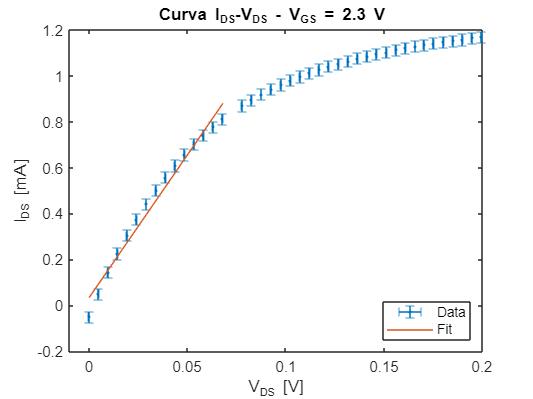

xx=linspace(0, max(Vd_fit), 100);
yy=p(1)*xx+p(2);
%ylim([-1,20.5])

xlim([-0.01, 0.2])

hold on 
plot(xx,yy*1e3)
hold off
legend('Data', 'Fit', 'Location','southeast')


i=i+1;
Vg(i)=2.3;
coeff(i)=p(1);
dcoeff(i)=dp(1);
fine_lin(i)=max(Vd_fit);

Risultati del fit lineare: 

- coefficiente = $12.4 \pm 0.3$ mA/V

- intercetta = $34 \pm 12$ $\mu$A 

- 
$$\chi^2_{norm} = 3.2$$


Su questa provo anche modello completo, che vale per $V_{DS}<V_{GS}-V_T \simeq 0.2$ V: 


$$I_{DS} = - K_n V_T + K_n V_{GS} V_{DS} - \frac{K_n}{2} V_{DS}^2$$
 

Id_fit=Id(1:50);
Vd_fit=Vd(1:length(Id_fit));
Vout=Id/R;

dig_Vout=10*2^(-12); %digitalizzazione
dig_V=1*2^(-12); %digitalizzazione
dVd=dig_V*ones(length(Id), 1);
dId=sqrt((dig_Vout/R)^2+(Vout*dR/R^2).^2); %digitalizzazione
dId_fit=dId(1:length(Id_fit));
errorbar(Vd, Id*1e3, dId*1e3, dId*1e3, dVd, dVd, '.')
title('Curva I_{DS}-V_{DS} - V_{GS} = 2.3 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{DS} [V]')

pin=[-0.25*2.1, 0.25*2.3, -0.25/2]'

pin =    -0.5250
    0.5750
   -0.1250


modello = @(p,x)(p(1)+x*p(2)+x.^2*p(3));
[p,resnorm,JJ,COVB,chi2n]=nlinfit(Vd_fit, Id_fit,modello,pin,'Weights', dId_fit.^(-2));
parametri_fit=p;
p(1)

ans =      1.104887695328643e-04


p(2)

ans =    0.011229128192124


p(3)

ans =   -0.028890076193509


for i=1 : length(p)
err_parametri_fit(i)=sqrt(COVB(i,i));
end
err_parametri_fit

err_parametri_fit =     0.0000    0.0004    0.0016


chisq_norm=chi2n

chisq_norm =    5.035046781304134


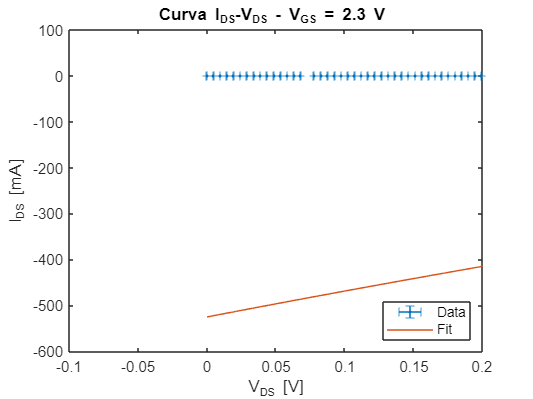

xx=linspace(0,max(Vd_fit), 1000);
yy=pin(1)+xx*pin(2)+xx.^2*pin(3);
hold on 
plot(xx,yy*1e3)
hold off
legend('Data', 'Fit', 'Location','southeast')
xlim([-0.1, 0.2])

Fit fatto per $V_{DS}$ fino a 0.12 V. 

$I_{DS}$ **vs **$V_{DS}$ **per **$V_{GS}$ **= 2.4 V**

R=100;%ohm
dR=1;
datamat=readmatrix('Data LAB es 7 vg 2,4');
Vd=datamat(:,1);
Id=datamat(:,2)*1e-3; %in A, misure in mA

Id_fit=Id(1:15);
Vd_fit=Vd(1:length(Id_fit));
Vout=Id/R;

dig_Vout=20*2^(-12); %digitalizzazione
dig_V=2*2^(-12); %digitalizzazione
dVd=dig_V*ones(length(Id), 1);
dId=sqrt((dig_Vout/R)^2+(Vout*dR/R^2).^2); %digitalizzazione
dId_fit=dId(1:length(Id_fit));
errorbar(Vd, Id*1e3, dId*1e3, dId*1e3, dVd, dVd, '.')
title('Curva I_{DS}-V_{DS} - V_{GS} = 2.4 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{DS} [V]')

%fit
[p, dp, chiqn, prod, corr]= fitpoli(1,Vd_fit, Id_fit, dId_fit);
coefficiente=p(1)

coefficiente =    0.025290326094988


dcoefficiente=dp(1)

dcoefficiente =      6.093005700481785e-04


intercetta=p(2)

intercetta =      4.892026879128788e-05


dintercetta=dp(2)

dintercetta =      2.407662320834529e-05


chiqn

chiqn =    2.073897028871960


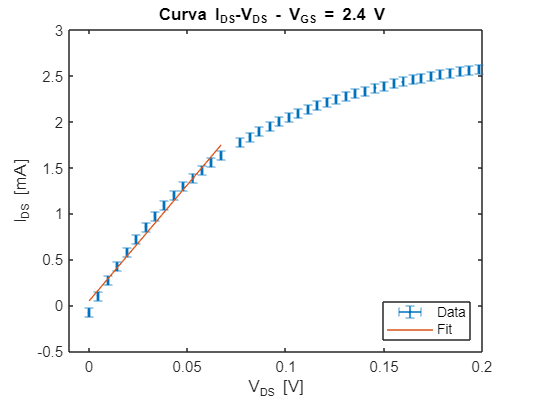

xx=linspace(0, max(Vd_fit), 100);
yy=p(1)*xx+p(2);
%ylim([-1,20.5])

xlim([-0.01, 0.2])

hold on 
plot(xx,yy*1e3)
hold off
legend('Data', 'Fit', 'Location','southeast')


i=i+1;
Vg(i)=2.4;
coeff(i)=p(1);
dcoeff(i)=dp(1);
fine_lin(i)=max(Vd_fit);

Risultati del fit lineare: 

- coefficiente = $67.5 \pm 0.6$ mA/V

- intercetta = $46 \pm 24$ $\mu$A 

- 
$$\chi^2_{norm} = 6.2$$


$I_{DS}$ **vs **$V_{DS}$ **per **$V_{GS}$ **= 2.6 V**

R=100;%ohm
dR=1;
datamat=readmatrix('Data LAB es 7 vg 2,6');
Vd=datamat(:,1);
Id=datamat(:,2)*1e-3; %in A, misure in mA

Id_fit=Id(1:15);
Vd_fit=Vd(1:length(Id_fit));
Vout=Id/R;

dig_Vout=20*2^(-12); %digitalizzazione
dig_V=2*2^(-12); %digitalizzazione
dVd=dig_V*ones(length(Id), 1);
dId=sqrt((dig_Vout/R)^2+(Vout*dR/R^2).^2); %digitalizzazione
dId_fit=dId(1:length(Id_fit));
errorbar(Vd, Id*1e3, dId*1e3, dId*1e3, dVd, dVd, '.')
title('Curva I_{DS}-V_{DS} - V_{GS} = 2.6 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{DS} [V]')

%fit
[p, dp, chiqn, prod, corr]= fitpoli(1,Vd_fit, Id_fit, dId_fit);
coefficiente=p(1)

coefficiente =    0.067459652427068


dcoefficiente=dp(1)

dcoefficiente =      6.257807576269547e-04


intercetta=p(2)

intercetta =      4.612715526152063e-05


dintercetta=dp(2)

dintercetta =      2.401902115511731e-05


chiqn

chiqn =    6.245604419466873


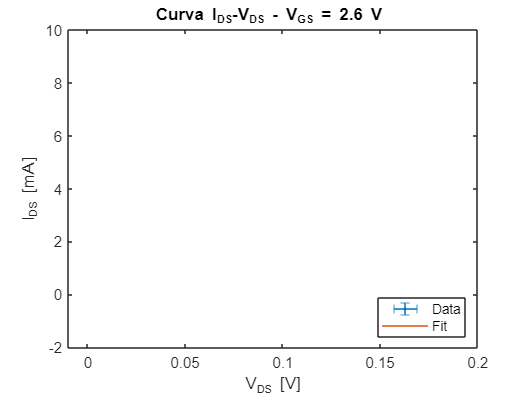

xx=linspace(0, max(Vd_fit), 100);
yy=p(1)*xx+p(2);
%ylim([-1,20.5])

xlim([-0.01, 0.2])

hold on 
plot(xx,yy*1e3)
hold off
legend('Data', 'Fit', 'Location','southeast')


i=i+1;
Vg(i)=2.6;
coeff(i)=p(1);
dcoeff(i)=dp(1);
fine_lin(i)=max(Vd_fit);

Risultati del fit lineare: 

- coefficiente = $67.5 \pm 0.6$ mA/V

- intercetta = $46 \pm 24$ $\mu$A 

- 
$$\chi^2_{norm} = 6.2$$


$I_{DS}$ **vs **$V_{DS}$ **per **$V_{GS}$ **= 3 V**

R=100;%ohm
dR=1;
datamat=readmatrix('Data LAB es 7');
Vd=datamat(:,1);
Id=datamat(:,2)*1e-3; %in A, misure in mA

Id_fit=Id(1:80);
Vd_fit=Vd(1:80);
Vout=Id/R;

dig_Vout=20*2^(-12); %digitalizzazione
dig_V=2*2^(-12); %digitalizzazione
dVd=dig_V*ones(length(Id), 1);
dId=sqrt((dig_Vout/R)^2+(Vout*dR/R^2).^2); %digitalizzazione
dId_fit=dId(1:80);
errorbar(Vd, Id*1e3, dId*1e3, dId*1e3, dVd, dVd, '.')
title('Curva I_{DS}-V_{DS} - V_{GS} = 3 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{DS} [V]')

%fit
[p, dp, chiqn, prod, corr]= fitpoli(1,Vd_fit, Id_fit, dId_fit);
coefficiente=p(1)

coefficiente =    0.176496025186935


dcoefficiente=dp(1)

dcoefficiente =      1.738310692109091e-04


intercetta=p(2)

intercetta =      1.984504081704794e-04


dintercetta=dp(2)

dintercetta =      1.076512577729467e-05


chiqn

chiqn =   33.937865089576619


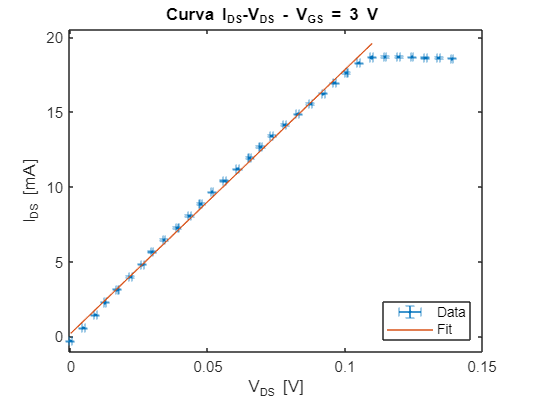

xx=linspace(0, max(Vd_fit), 100);
yy=p(1)*xx+p(2);
ylim([-1,20.5])

hold on 
plot(xx,yy*1e3)
hold off
legend('Data', 'Fit', 'Location','southeast')


i=i+1;
Vg(i)=3;
coeff(i)=p(1);
dcoeff(i)=dp(1);
fine_lin(i)=max(Vd_fit);

Risultati del fit lineare: 

- coefficiente = $176.5 \pm 0.2$ mA/V

- intercetta = $0.20 \pm 0.01$ mA 

- 
$$\chi^2_{norm} = 33.9$$


$I_{DS}$ **vs **$V_{DS}$ **per **$V_{GS}$ **= 4 V**

R=100;%ohm
dR=1;
datamat=readmatrix('Data LAB es 7 vg 4');
Vd=datamat(:,1);
Id=datamat(:,2)*1e-3; %in A, misure in mA

Id_fit=Id(1:33);
Vd_fit=Vd(1:length(Id_fit));
Vout=Id/R;

dig_Vout=20*2^(-12); %digitalizzazione
dig_V=2*2^(-12); %digitalizzazione
dVd=dig_V*ones(length(Id), 1);
dId=sqrt((dig_Vout/R)^2+(Vout*dR/R^2).^2); %digitalizzazione
dId_fit=dId(1:length(Id_fit));
errorbar(Vd, Id*1e3, dId*1e3, dId*1e3, dVd, dVd, '.')
title('Curva I_{DS}-V_{DS} - V_{GS} = 4 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{DS} [V]')

%fit
[p, dp, chiqn, prod, corr]= fitpoli(1,Vd_fit, Id_fit, dId_fit);
coefficiente=p(1)

coefficiente =    0.377290037690893


dcoefficiente=dp(1)

dcoefficiente =      5.527675082266169e-04


intercetta=p(2)

intercetta =     -5.880341595138269e-04


dintercetta=dp(2)

dintercetta =      1.667571771693464e-05


chiqn

chiqn =    5.935279809314909


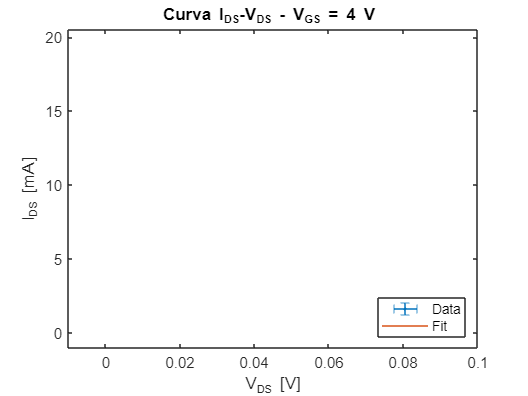

xx=linspace(0, max(Vd_fit), 100);
yy=p(1)*xx+p(2);
ylim([-1,20.5])

xlim([-0.01, 0.1])

hold on 
plot(xx,yy*1e3)
hold off
legend('Data', 'Fit', 'Location','southeast')



i=i+1;
Vg(i)=4;
coeff(i)=p(1);
dcoeff(i)=dp(1);
fine_lin(i)=max(Vd_fit);

Risultati del fit lineare: 

- coefficiente = $377.3 \pm 0.6$ mA/V

- intercetta = $-0.59 \pm 0.02$ mA 

- 
$$\chi^2_{norm} = 5.9$$


Qui si ferma a 20 mA perché OpAmp non può lavorare a correnti maggiori: non ha senso vedere lunghezza zona lineare qui. 

**Studio del coefficiente **$I_{DS}/V_{DS}$ **al variare di **$V_{GS}$

Il valore atteso per il coefficiente $I_{DS}/V_{DS}$, se $V_{DS} \ll V_{GS}-V_T$, è dato da :

$K_n (V_{GS}-V_T)$, con $K_n = 0.25$ mA/V$^2$. 

Fit lineare di $I_{DS}/V_{DS}$ VS $V_{GS}$:

errorbar(Vg, coeff, dcoeff, dcoeff, '.')
%fit
[p, dp, chiqn, prod, corr]= fitpoli(1,Vg, coeff, dcoeff);

coefficiente=p(1)

coefficiente =    NaN


dcoefficiente=dp(1)

dcoefficiente =    NaN


intercetta=p(2)

intercetta =    NaN


dintercetta=dp(2)

dintercetta =    NaN


Vt=-intercetta/coefficiente

Vt =    NaN


dVt=sqrt((dintercetta/coefficiente)^2+(intercetta/coefficiente^2*dcoefficiente)^2)

dVt =    NaN


chiqn

chiqn =    NaN


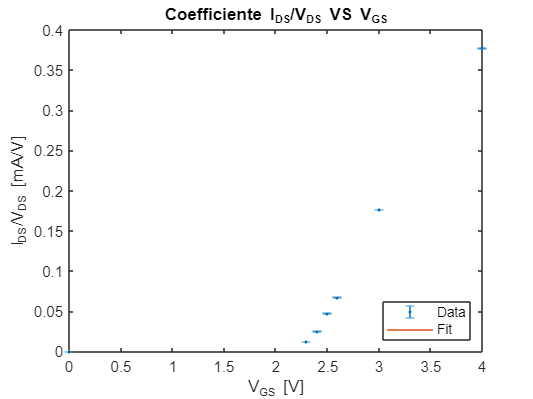

xx=linspace(min(Vg)-0.5, max(Vg)+0.5, 100);
yy=p(1)*xx+p(2);

hold on 
plot(xx,yy)
hold off
legend('Data', 'Fit', 'Location','southeast')
title('Coefficiente I_{DS}/V_{DS} VS V_{GS}')
xlabel('V_{GS} [V]')
ylabel('I_{DS}/V_{DS} [mA/V]')

Risultati del fit lineare: 

- $K_n$ = $0.2239 \pm 0.0003$ mA/V$^2$

- intercetta = $-K_n V_T$= $-0.5004 \pm 0.0009$ mA/V 

- $V_T = 2.235 \pm 0.005$ V

- 
$$\chi^2_{norm} = 767$$


Errori su $I_{DS}/V_{DS}$ sono sottostimati perché il chi quadro normalizzato viene grande.

## Es. 8: Corrente di Drain VS Tensione di Gain

Montato con Rtrans = 100 Ohm 

Prima misura (sbagliato)

Decidiamo Vdrain= 0.08 (regime lineare, ma non troppo alto per avere I sotto 10 mA e Vg non basso) 

Abbiamo inizialmente fatto variare Vgate a partire da 1,5 V ed è costantemente 0 fino a Vg = 2 V. Per questo motivo, scegliamo intervallo Vgate a partire da 2 e fino alla Vg per cui si rimane sotto i 10 mA per corrente Ids

Vg tra 2 e 2.9 V 

R=100;%ohm
dR=1;
Vds=0.08;
datamat=readmatrix('Data LAB es 8');
Vgs=datamat(:,1);
Ids=datamat(:,2); %in A, misure in mA

Vout=Ids/R;

dig_V=2*2^(-12); %digitalizzazione
dVgs=dig_V*ones(length(Ids), 1);
dIds=Ids*0.01; %tolleranza resistenza propagata
dig_Vout=Vout.*sqrt((dIds./Ids).^2+(dR/R).^2); 


%preparo i dati per il fit
j=1;
aa=Vgs>2.2;
Ids_fit = ones(1, sum(aa));
Vgs_fit = ones(1, sum(aa));
dIds_fit = ones(1, sum(aa));
for i = 1 : length(Ids)
    if aa(i)==1
        Ids_fit(j)=Ids(i);
        Vgs_fit(j)=Vgs(i);
        dIds_fit(j)=dIds(i);
        j=j+1;
    end
end

%fit
pin=[60, 2]';
modello = @(p,x)(p(1)/2*((x-p(2)).^2));
%[pout, dp, chiqnor, prob, corr] = fitnonlin(@modello_curvaVgId, pin, Vgs, Ids, dIds)
[p,resnorm,JJ,COVB,chi2n]=nlinfit(Vgs_fit, Ids_fit, modello, pin, 'Weights', dIds_fit.^(-2));
parametri_fit=p

parametri_fit =    29.9023
    2.0528


for i=1:length(p)
    err_parametri(i)=sqrt(COVB(i,i));
end
err_parametri

err_parametri =     0.2657    0.0016


chi2=chi2n

chi2 =   13.612426843141012


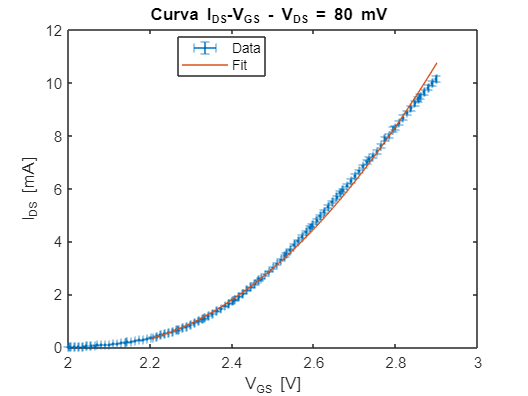



%grafico
errorbar(Vgs, Ids, dIds, dIds, dVgs, dVgs, '.')
hold on
plot(Vgs_fit, modello(parametri_fit, Vgs_fit))
hold off
title('Curva I_{DS}-V_{GS} - V_{DS} = 80 mV ')
ylabel('I_{DS} [mA]')
xlabel('V_{GS} [V]')
legend('Data', 'Fit', 'Location','best')

Ora ci mettiamo in saturazione (V drain 1 V)  - Vg tra 2 e 2.6 V 

R=100;%ohm
dR=1;
Vds=1;
datamat=readmatrix('Data LAB es 8 vd 1');
Vgs=datamat(:,1);
Ids=datamat(:,2); %in A, misure in mA

Vout=Ids/R;

dig_V=2*2^(-12); %digitalizzazione
dVgs=dig_V*ones(length(Ids), 1);
dIds=Ids*0.01; %tolleranza resistenza propagata
dig_Vout=Vout.*sqrt((dIds./Ids).^2+(dR/R).^2); 

%preparo i dati per il fit
j=1;
aa=Vgs>2.2;
Ids_fit = ones(1, sum(aa));
Vgs_fit = ones(1, sum(aa));
dIds_fit = ones(1, sum(aa));
for i = 1 : length(Ids)
    if aa(i)==1
        Ids_fit(j)=Ids(i);
        Vgs_fit(j)=Vgs(i);
        dIds_fit(j)=dIds(i);
        j=j+1;
    end
end

%fit
pin=[60, 2]';
modello = @(p,x)(p(1)/2*((x-p(2)).^2));
%[pout, dp, chiqnor, prob, corr] = fitnonlin(@modello_curvaVgId, pin, Vgs, Ids, dIds)
[p,resnorm,JJ,COVB,chi2n]=nlinfit(Vgs_fit, Ids_fit, modello, pin, 'Weights', dIds_fit.^(-2));
parametri_fit=p

parametri_fit =    65.0675
    2.0887


for i=1:length(p)
    err_parametri(i)=sqrt(COVB(i,i));
end
err_parametri

err_parametri =     1.8883    0.0035


chi2=chi2n

chi2 =   86.033128372041389


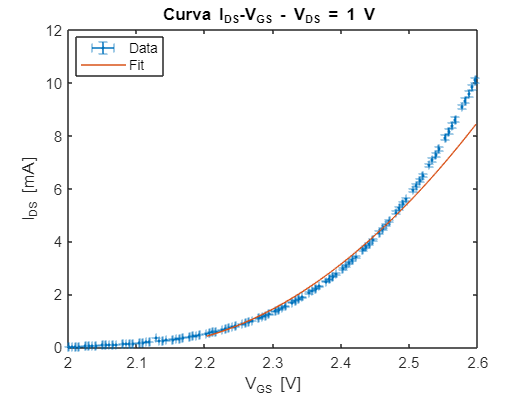


l=1;
kn(l)=p(1); %array per prendere i risultati dei fit nel regime di saturazione
Vt(l)=p(2);
dkn(l)=err_parametri(1);
l=l+1;



%grafico
errorbar(Vgs, Ids, dIds, dIds, dVgs, dVgs, '.')
hold on
plot(Vgs_fit, modello(parametri_fit, Vgs_fit))
hold off
title('Curva I_{DS}-V_{GS} - V_{DS} = 1 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{GS} [V]')
legend('Data', 'Fit', 'Location','best')

## Es. 9: Corrente di Drain VS Tensione di Gain per diversi Vds

Regime lineare

1) Vdrain 0.1 e 2.2.6 V 

R=100;%ohm
dR=1;
Vds=0.1;
datamat=readmatrix('Data LAB es 9');
Vgs=datamat(:,1);
Ids=datamat(:,2); %in A, misure in mA

Vout=Ids/R;

dig_V=2*2^(-12); %digitalizzazione
dVgs=dig_V*ones(length(Ids), 1);
dIds=Ids*0.01; %tolleranza resistenza propagata
dig_Vout=Vout.*sqrt((dIds./Ids).^2+(dR/R).^2); 

%preparo i dati per il fit
j=1;
aa=Vgs>2.2;
Ids_fit = ones(1, sum(aa));
Vgs_fit = ones(1, sum(aa));
dIds_fit = ones(1, sum(aa));
for i = 1 : length(Ids)
    if aa(i)==1
        Ids_fit(j)=Ids(i);
        Vgs_fit(j)=Vgs(i);
        dIds_fit(j)=dIds(i);
        j=j+1;
    end
end

%fit
pin=[60, 2]';
modello = @(p,x)(p(1)/2*((x-p(2)).^2));
%[pout, dp, chiqnor, prob, corr] = fitnonlin(@modello_curvaVgId, pin, Vgs, Ids, dIds)
[p,resnorm,JJ,COVB,chi2n]=nlinfit(Vgs_fit, Ids_fit, modello, pin, 'Weights', dIds_fit.^(-2));
parametri_fit=p

parametri_fit =    35.4291
    2.0605


for i=1:length(p)
    err_parametri(i)=sqrt(COVB(i,i));
end
err_parametri

err_parametri =     0.5740    0.0022


chi2=chi2n

chi2 =   23.324891901510430


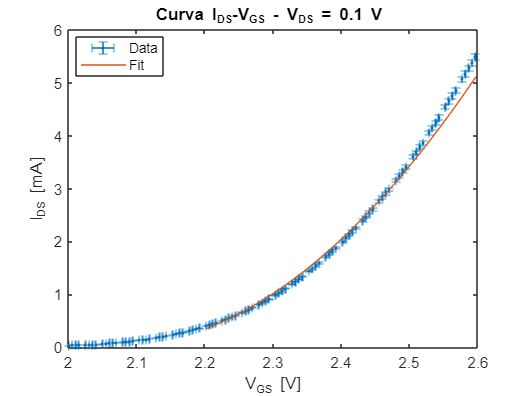



%grafico
errorbar(Vgs, Ids, dIds, dIds, dVgs, dVgs, '.')
hold on
plot(Vgs_fit, modello(parametri_fit, Vgs_fit))
hold off
title('Curva I_{DS}-V_{GS} - V_{DS} = 0.1 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{GS} [V]')
legend('Data', 'Fit', 'Location','best')

2) 2-2.7 V con Vd 0.09V 

R=100;%ohm
dR=1;
Vds=0.09;
datamat=readmatrix('Data LAB es 9 2');
Vgs=datamat(:,1);
Ids=datamat(:,2); %in A, misure in mA

Vout=Ids/R;

dig_V=2*2^(-12); %digitalizzazione
dVgs=dig_V*ones(length(Ids), 1);
dIds=Ids*0.01; %tolleranza resistenza propagata
dig_Vout=Vout.*sqrt((dIds./Ids).^2+(dR/R).^2); 

%preparo i dati per il fit
j=1;
aa=Vgs>2.2;
Ids_fit = ones(1, sum(aa));
Vgs_fit = ones(1, sum(aa));
dIds_fit = ones(1, sum(aa));
for i = 1 : length(Ids)
    if aa(i)==1
        Ids_fit(j)=Ids(i);
        Vgs_fit(j)=Vgs(i);
        dIds_fit(j)=dIds(i);
        j=j+1;
    end
end

%fit
pin=[60, 2]';
modello = @(p,x)(p(1)/2*((x-p(2)).^2));
%[pout, dp, chiqnor, prob, corr] = fitnonlin(@modello_curvaVgId, pin, Vgs, Ids, dIds)
[p,resnorm,JJ,COVB,chi2n]=nlinfit(Vgs_fit, Ids_fit, modello, pin, 'Weights', dIds_fit.^(-2));
parametri_fit=p

parametri_fit =    34.6111
    2.0638


for i=1:length(p)
    err_parametri(i)=sqrt(COVB(i,i));
end
err_parametri

err_parametri =     0.4613    0.0020


chi2=chi2n

chi2 =   20.483308586710574


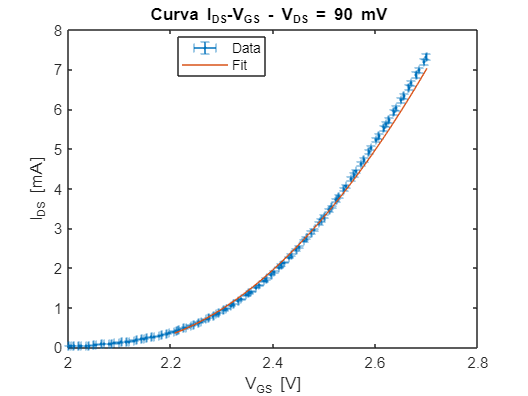



%grafico
errorbar(Vgs, Ids, dIds, dIds, dVgs, dVgs, '.')
hold on
plot(Vgs_fit, modello(parametri_fit, Vgs_fit))
hold off
title('Curva I_{DS}-V_{GS} - V_{DS} = 90 mV ')
ylabel('I_{DS} [mA]')
xlabel('V_{GS} [V]')
legend('Data', 'Fit', 'Location','best')

Regime saturazione: 

1) Vd = 3.3 V e Vg tra 2 e 2.5V 

R=100;%ohm
dR=1;
Vds=3.3;
datamat=readmatrix('Data LAB es 9 vd 3,3');
Vgs=datamat(:,1);
Ids=datamat(:,2); %in A, misure in mA

Vout=Ids/R;

dig_V=2*2^(-12); %digitalizzazione
dVgs=dig_V*ones(length(Ids), 1);
dIds=Ids*0.01; %tolleranza resistenza propagata
dig_Vout=Vout.*sqrt((dIds./Ids).^2+(dR/R).^2); 

%preparo i dati per il fit
j=1;
aa=Vgs>2.2;
Ids_fit = ones(1, sum(aa));
Vgs_fit = ones(1, sum(aa));
dIds_fit = ones(1, sum(aa));
for i = 1 : length(Ids)
    if aa(i)==1
        Ids_fit(j)=Ids(i);
        Vgs_fit(j)=Vgs(i);
        dIds_fit(j)=dIds(i);
        j=j+1;
    end
end

%fit
pin=[60, 2]';
modello = @(p,x)(p(1)/2*((x-p(2)).^2));
%[pout, dp, chiqnor, prob, corr] = fitnonlin(@modello_curvaVgId, pin, Vgs, Ids, dIds)
[p,resnorm,JJ,COVB,chi2n]=nlinfit(Vgs_fit, Ids_fit, modello, pin, 'Weights', dIds_fit.^(-2));
parametri_fit=p

parametri_fit =    59.9639
    2.0751


for i=1:length(p)
    err_parametri(i)=sqrt(COVB(i,i));
end
err_parametri

err_parametri =     1.5018    0.0029


chi2=chi2n

chi2 =   40.274108876024087


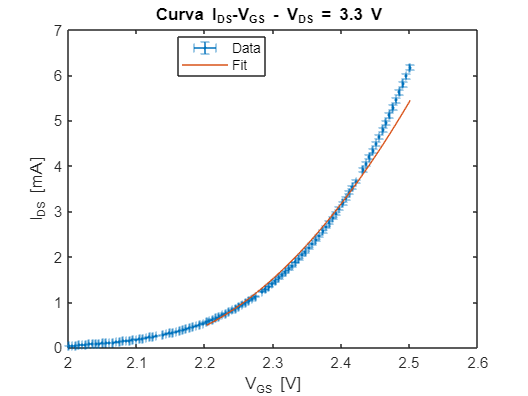


kn(l)=p(1); %array per prendere i risultati dei fit nel regime di saturazione
Vt(l)=p(2);
dkn(l)=err_parametri(1);
l=l+1;

%grafico
errorbar(Vgs, Ids, dIds, dIds, dVgs, dVgs, '.')
hold on
plot(Vgs_fit, modello(parametri_fit, Vgs_fit))
hold off
title('Curva I_{DS}-V_{GS} - V_{DS} = 3.3 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{GS} [V]')
legend('Data', 'Fit', 'Location','best')

2) Vd = 4 V e Vg tra 2 e 2.5 V 

R=100;%ohm
dR=1;
Vds=4;
datamat=readmatrix('Data LAB es 9 vd 4');
Vgs=datamat(:,1);
Ids=datamat(:,2); %in A, misure in mA

Vout=Ids/R;

dig_V=2*2^(-12); %digitalizzazione
dVgs=dig_V*ones(length(Ids), 1);
dIds=Ids*0.01; %tolleranza resistenza propagata
dig_Vout=Vout.*sqrt((dIds./Ids).^2+(dR/R).^2); 

%preparo i dati per il fit
j=1;
aa=Vgs>2.2;
Ids_fit = ones(1, sum(aa));
Vgs_fit = ones(1, sum(aa));
dIds_fit = ones(1, sum(aa));
for i = 1 : length(Ids)
    if aa(i)==1
        Ids_fit(j)=Ids(i);
        Vgs_fit(j)=Vgs(i);
        dIds_fit(j)=dIds(i);
        j=j+1;
    end
end

%fit
pin=[60, 2]';
modello = @(p,x)(p(1)/2*((x-p(2)).^2));
%[pout, dp, chiqnor, prob, corr] = fitnonlin(@modello_curvaVgId, pin, Vgs, Ids, dIds)
[p,resnorm,JJ,COVB,chi2n]=nlinfit(Vgs_fit, Ids_fit, modello, pin, 'Weights', dIds_fit.^(-2));
parametri_fit=p

parametri_fit =    60.3352
    2.0738


for i=1:length(p)
    err_parametri(i)=sqrt(COVB(i,i));
end
err_parametri

err_parametri =     1.5590    0.0030


chi2=chi2n

chi2 =   42.336079228461756


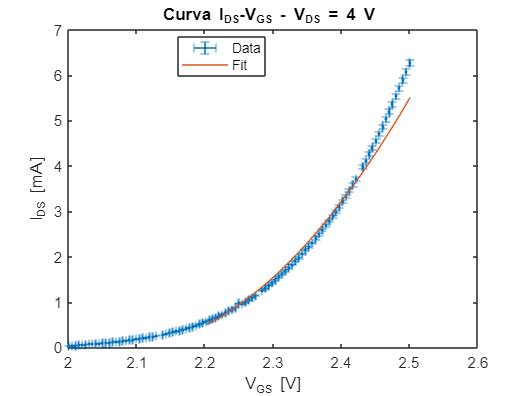



kn(l)=p(1); %array per prendere i risultati dei fit nel regime di saturazione
Vt(l)=p(2);
dkn(l)=err_parametri(1);


%grafico
errorbar(Vgs, Ids, dIds, dIds, dVgs, dVgs, '.')
hold on
plot(Vgs_fit, modello(parametri_fit, Vgs_fit))
hold off
title('Curva I_{DS}-V_{GS} - V_{DS} = 4 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{GS} [V]')
legend('Data', 'Fit', 'Location','best')

Dai risultati misuriamo ora Kn:

knm=mean(kn)

knm =   61.788867049877531


dknm=knm*sqrt(((dkn(1)/kn(1))^2)+((dkn(2)/kn(2))^2)+((dkn(3)/kn(3))^2))

dknm =    2.856451962842784


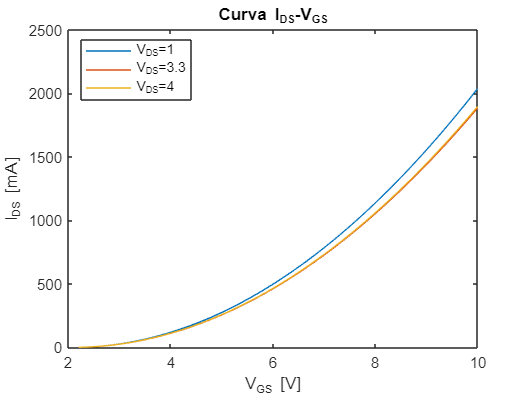


%grafico ora i risultati dei fit per i vari Vdt
xx=linspace(2.2, 10, 1000);
yy=modello([kn(1), Vt(1)], xx);
tt=modello([kn(2), Vt(2)], xx);
zz=modello([kn(3), Vt(3)], xx);

plot(xx, yy);
hold on
plot(xx, tt);
plot(xx, zz);
hold off
title('Curva I_{DS}-V_{GS}')
ylabel('I_{DS} [mA]')
xlabel('V_{GS} [V]')
legend('V_{DS}=1', 'V_{DS}=3.3', 'V_{DS}=4', 'Location','best')

## Es. 11

Prima misura: V

Con Op37 abbiamo usato R=150 Ohm 

R=150;%ohm
dR=1.5;
Vds=2.5;
datamat=readmatrix('Data LAB es 11 OP37');
Vgs=datamat(:,1);
Ids=datamat(:,2); %in A, misure in mA

Vout=Ids/R;

dig_V=2*2^(-12); %digitalizzazione
dVgs=dig_V*ones(length(Ids), 1);
dIds=Ids*0.01; %tolleranza resistenza propagata
dig_Vout=Vout.*sqrt((dIds./Ids).^2+(dR/R).^2); 

%preparo i dati per il fit
j=1;
aa=Vgs>2.2;
for i= 1 : length(Vgs) %gli ultimi punti tornano a calare perchè I>35mA
    if Ids(i)>31
        aa(i)=0;
    end
end
Ids_fit = ones(1, sum(aa));
Vgs_fit = ones(1, sum(aa));
dIds_fit = ones(1, sum(aa));
for i = 1 : (length(Ids))
    if aa(i)==1
        Ids_fit(j)=Ids(i);
        Vgs_fit(j)=Vgs(i);
        dIds_fit(j)=dIds(i);
        j=j+1;
    end
end

%fit
pin=[60, 2]';
modello = @(p,x)(p(1)/2*((x-p(2)).^2));
%[pout, dp, chiqnor, prob, corr] = fitnonlin(@modello_curvaVgId, pin, Vgs, Ids, dIds)
[p,resnorm,JJ,COVB,chi2n]=nlinfit(Vgs_fit, Ids_fit, modello, pin, 'Weights', dIds_fit.^(-2));
parametri_fit=p

parametri_fit =    91.1502
    2.0958


for i=1:length(p)
    err_parametri(i)=sqrt(COVB(i,i));
end
err_parametri

err_parametri =     5.5860    0.0085


chi2=chi2n

chi2 =      1.657759570100640e+02


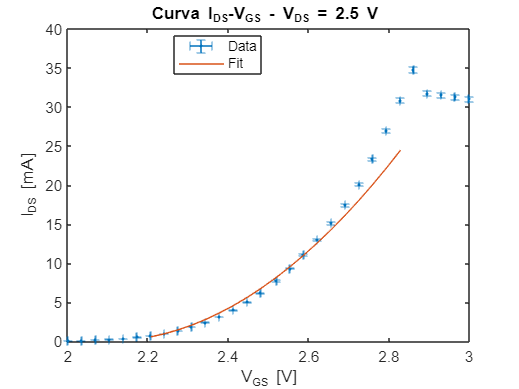


%grafico
errorbar(Vgs, Ids, dIds, dIds, dVgs, dVgs, '.')
hold on
plot(Vgs_fit, modello(parametri_fit, Vgs_fit))
hold off
title('Curva I_{DS}-V_{GS} - V_{DS} = 2.5 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{GS} [V]')
legend('Data', 'Fit', 'Location','best')

La seconda misura è con sempre OP, un altro componente.

R=150;%ohm
dR=1.5;
Vds=2.5;
datamat=readmatrix('Data LAB es 11 OP37 2');
Vgs=datamat(:,1);
Ids=datamat(:,2); %in A, misure in mA

Vout=Ids/R;

dig_V=2*2^(-12); %digitalizzazione
dVgs=dig_V*ones(length(Ids), 1);
dIds=Ids*0.01; %tolleranza resistenza propagata
dig_Vout=Vout.*sqrt((dIds./Ids).^2+(dR/R).^2); 

%preparo i dati per il fit
j=1;
aa=Vgs>2.2;
Ids_fit = ones(1, sum(aa)-4);
Vgs_fit = ones(1, sum(aa)-4);
dIds_fit = ones(1, sum(aa)-4);
for i = 1 : (length(Ids)-4)  %gli ultimi punti tornano a calare perchè I>35mA
    if aa(i)==1
        Ids_fit(j)=Ids(i);
        Vgs_fit(j)=Vgs(i);
        dIds_fit(j)=dIds(i);
        j=j+1;
    end
end

%fit
pin=[60, 2]';
modello = @(p,x)(p(1)/2*((x-p(2)).^2));
%[pout, dp, chiqnor, prob, corr] = fitnonlin(@modello_curvaVgId, pin, Vgs, Ids, dIds)
[p,resnorm,JJ,COVB,chi2n]=nlinfit(Vgs_fit, Ids_fit, modello, pin, 'Weights', dIds_fit.^(-2));
parametri_fit=p

parametri_fit =    93.9800
    2.0970


for i=1:length(p)
    err_parametri(i)=sqrt(COVB(i,i));
end
err_parametri

err_parametri =     5.6733    0.0085


chi2=chi2n

chi2 =      1.756064481671150e+02


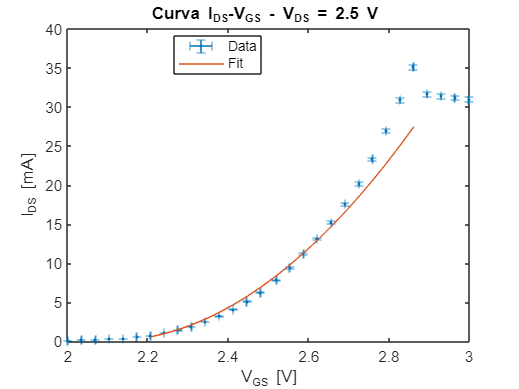


%grafico
errorbar(Vgs, Ids, dIds, dIds, dVgs, dVgs, '.')
hold on
plot(Vgs_fit, modello(parametri_fit, Vgs_fit))
hold off
title('Curva I_{DS}-V_{GS} - V_{DS} = 2.5 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{GS} [V]')
legend('Data', 'Fit', 'Location','best')

## Es. 13

Nell'ATTENZIONE : cambiare valore finale di Vgs 

Andare in FET_vs_DRAIN.vi: alla fine nel 9 modifica il valore di CB22 (ao0) a 0: modificare quella costante da 0 al valore desiderato 

Poi nel primo frame (0) cambiare l'intervallo massimo da 5 a 10, così si può andare negativi 

Modificato e creato nuovo vi: JFET_vs_DRAIN 

**Partiamo da curva Id-Vds**

Vogliamo rimanere sempre sotto 10 mA

Soglia è tra -7  (I sempre 0) e -6.5 V (fa retta)

Misura 1: Vg= -6.5 e Vd tra 0 e 2.4 V (misura 13-6)

Misura 2: Vg = -6.4, Vd tra 0 e 1.5 (misura 13-7)

**Curva Id-Vgs**

Misura 1: Vd=3.3 V e Vg tra -7 e -6.5  (misura 13-8)

Misura 2: Vd=2 V e Vg tra -7 e -6.4 (misura 13-9 )

**Curva Id-Vgs con generatore **

Mettiamo Vd = 2.5 (Misura Vdrain = 2.53 V) e Vg tra -7 e -6.35 

Misura 13-11

## Es. 15- simulazioni su TINA

Fissando Vs a 5 V, la corrente Id diminuisce all'aumentare di R1 o di R2.

Scelto il led LA 3366, con corrente massima 30 mA.

Fissando R1=330 Ohm, per ogni valore di R2 (>10 Ohm) abbiamo Id<20 mA, e quindi non rischiamo di danneggiare il LED.

## Es. 16 - simulazioni con LED su TINA

Aggiungendo il LED nella simulazione, abbiamo che la tensione di Source rispetto alla massa aumenta all'aumentare di Vs, saturando a 7 V quando Vs è 5V circa.

## Es. 17/18 - circuito con R2

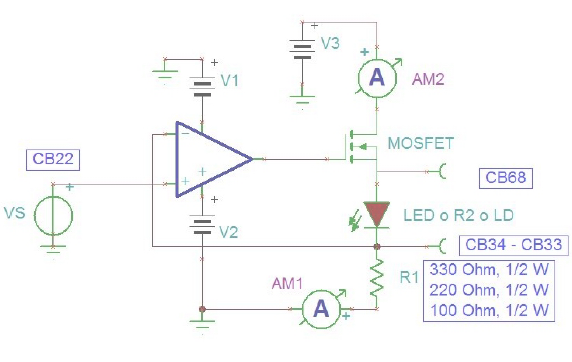

Montato il circuito nel seguente modo:

- R1 = R2 = 330 Ohm;

- OpAmp ua741 alimentato con $$\pm$$12 V;

- V3 = 12 V;

- Mosfet BS170.

Dopo aver visto qualitativamente la risposta del circuito a vari Vs con Traccia_Vin_Vout_2C, abbiamo utilizzato Traccia_Vin_Vout_diff per acquisire più misure variando Vs:

- Fondo scala 10 V per tutti i canali (CB68, CB33 e CB34, posizionati come in figura);

- Vs da 0.25 a 3.75 V;

- N misure = 50.

Acquisizioni prese:

R1=330;%ohm
dR1=3.3;
R2=330;%ohm
dR2=3.3;
datamat=readmatrix('Data LAB es 17 Vs CB33');
Vs=datamat(:,1);
Vr1=datamat(:,2); %potenziale a CB33/34

dVs=ones(1, length(Vs))*20/(2^(12)); %errore di digitalizzazione
dVr1=ones(1, length(Vr1))*20/(2^(12)); %errore di digitalizzazione

%misura ddp ai capi di R2
datamat=readmatrix('Data LAB es 17');
Vsource=datamat(:,1); %potenziale a CB68
Vs1=datamat(:,2); %potenziale a CB33/34

dVsource=ones(1, length(Vsource))*20/(2^(12)); %errore di digitalizzazione
dVs1=ones(1, length(Vs1))*20/(2^(12)); %errore di digitalizzazione

%fit sulle prime misure
[p, dp, chiqn, prod, corr]= fitpoli(1, Vs, Vr1, dVr1');
coefficiente=p(1)
dcoefficiente=dp(1)
intercetta=p(2)

coefficiente =    0.999948360847097


dintercetta=dp(2)

dcoefficiente =      6.699163479607214e-04


chiquadro=chiqn

intercetta =    0.001211278305808


xx=linspace(min(Vs), max(Vs), 1000);

dintercetta =    0.001507311783031


yy=p(1)*xx+p(2);

chiquadro =    0.150833408038377



%fit sulle seconde misure
[p, dp, chiqn, prod, corr]= fitpoli(1, Vsource, Vs1, dVs1');
coefficiente2=p(1)
dcoefficiente2=dp(1)
intercetta2=p(2)

coefficiente2 =    1.998436458332446


dintercetta2=dp(2)

dcoefficiente2 =      6.252561996858132e-04


chiquadro2=chiqn

intercetta2 =    0.003244526043552


xx2=linspace(min(Vsource), max(Vsource), 1000);

dintercetta2 =    0.001497397608305


yy2=p(1)*xx2+p(2);

chiquadro2 =    0.363469378080955




%Grafici
errorbar(Vsource, Vs1, dVsource, dVsource, dVs1, dVs1, '.') %grafico di Vs in funzione di Vc (CB33/34)
hold on
errorbar(Vs, Vr1, dVs, dVs, dVr1, dVr1, '.') %grafico di Vsource a CB68 in funzione di Vs (CB33/34)
plot(xx, yy)
plot(xx2, yy2)
hold off
title('Potenziali del circuito in funzione di Vs')
xlabel('Vs [V]')
ylabel('Vout [V]')
legend('Vout=Vsource', 'Vout=Vr1', 'Fit su Vout=Vsource', 'Fit su Vout=Vr1', 'Location', 'best')

Risultati fit lineare su Vs-Vr1 (dove Vr1 è CB33/34):

- coefficiente angolare = 0.9999 $$\pm$$ 0.0006;

- intercetta = (1.2 $$\pm$$ 1.5)e-3;

- $$\chi ^2_{norm}$$= 0.15.

Risultati fit lineare su Vs-Vsource (dove Vsource è CB68):

- coefficiente angolare = 1.9984 $$\pm$$ 0.0006;

- intercetta = (3.2 $$\pm$$ 1.5)e-3;

- $$\chi ^2_{norm}$$= 0.36

Entrambi i fit riportano un'intercetta che possiamo assumere come nulla.

Con il primo fit troviamo Vs=Vr1, almeno nel range di Vs testato.

Dal secondo fit invece vediamo Vsource=2Vs.

Entrambi i comportamenti sono spiegati nell'esercizio 19.

## Es. 19-

Dalle regole d'oro dell'OpAmp, V-=V+=Vs, quindi CB33=Vs.

Essendo la corrente che attraversa R2, I2=Vs/R1, da cui R2*I2=CB68-Vs.

Quindi Vs(R1+R2)=CB68*R1, da cui Vs=(CB68*R1)/(R1+R2).

Torna con le misure prese.

## Es. 20-

Vs da 0.25 a 3.75 V in 50 punti, altrimenti Vgate supera il fondo scala.

fondi scala 10 V

Misurando insieme CB68 e CB33 i segnali appaiono distorti, hanno una variazione di pendenza a voltaggi variabili.

Misuriamo uno alla volta, supponendo che il comportamento del circuito non vari tra una misura e l'altra.

Verificare se va tolto l'ultimo punto.

Sistemato il problema collegando bene CB33 e CB34

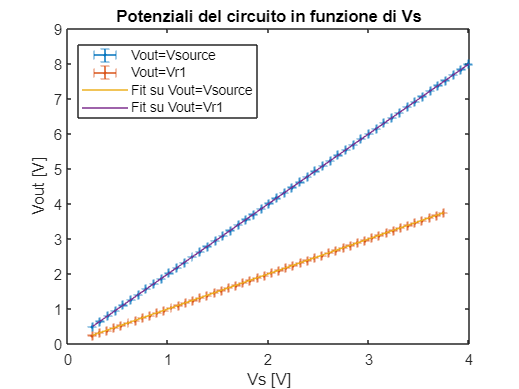

R1=330;%ohm
dR1=3.3;

coefficiente =    2.000030976188214


dcoefficiente =      6.699163479607214e-04


intercetta =    0.003024047623573


dintercetta =    0.001507311783031


chiquadro =    0.468529294234895


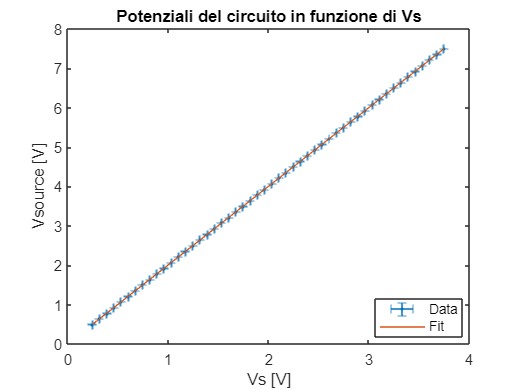

datamat=readmatrix('Data LAB es 20');
Vs=datamat(:,1);
Vsource=datamat(:,2); %potenziale a CB68

dVs=ones(1, length(Vs))*20/(2^(12)); %errore di digitalizzazione
dVsource=ones(1, length(Vsource))*20/(2^(12)); %errore di digitalizzazione

%fit sulle prime misure
[p, dp, chiqn, prod, corr]= fitpoli(1, Vs, Vsource, dVsource');
coefficiente=p(1)
dcoefficiente=dp(1)
intercetta=p(2)
dintercetta=dp(2)
chiquadro=chiqn
xx=linspace(min(Vs), max(Vs), 1000);
yy=p(1)*xx+p(2);

%Grafici
errorbar(Vs, Vsource, dVs, dVs, dVsource, dVsource, '.') %grafico di Vsource in funzione di Vs (CB68)
hold on
plot(xx, yy)
hold off
title('Potenziali del circuito in funzione di Vs')
xlabel('Vs [V]')
ylabel('Vsource [V]')
legend('Data', 'Fit', 'Location', 'best')

Risultati fit lineare su Vs-Vr1:

- coefficiente angolare = 2.0000 $$\pm$$ 0.0007;

- intercetta = (0.3 $$\pm$$ 1.5)e-3;

- $$\chi ^2_{norm}$$= 0.47.

## Es. 21- LED al posto di R2

Led LA 3366

Anodo è la stanghetta più lunga.

Vs da 0.25 a 3.75 V in 50 punti, altrimenti Vgate supera il fondo scala.

fondi scala 10 V

## Es. 22- curva caratteristica del LED

Vs da 0.01 a 8.5 V

fondi scala 10 V

R1=330 Ohm

Grafico con I-V diodo con 100 punti

Misura 1: LA 3366 (forse parte da 0.001);

Misura 2: HLMP C115;

Misura 3: HLMP C115 (con R1=100 Ohm);

Misura 4: WP 9294 QBC (con R1=100 Ohm).

# Sezione Risultati

## Es. 2 - Tensione di Soglia del MOSFET

$V_T$ è intorno ai 2 V, in accordo con il valore tipico riportato dal datasheet, 2.1 V